## Part 1

### define x,t,m

x = linspace(0,1,200);
t = linspace(0,10,201);
m = 0;

### define ic


$$\textrm{ic}\;u\left(x,0\right)=2e^x$$


function ic = ic_heat(x)
    ic = 2*exp(x);
end

### define bc


$$u\left(0,t\right)=0$$



$$u\left(2,t\right)=50$$


function [pl,ql,pr,qr] = bc_heat(xl,ul,xr,ur,t)
    pr = ur - 35;
    pl = ul;
    qr = 0;
    ql = 0;
end

### define equation pde


$$\frac{\partial^2 u}{\partial x^2 }-\frac{\;1}{c^2 }\frac{\partial u}{\partial x}=0$$


$\frac{\;1}{c^2 }=50\Rightarrow$c = 50


$$f=\frac{\;\partial u}{\partial x}$$



$$s=0$$


function [c,f,s] = pde_heat(x,t,u,DuDx)
    c = 50;
    f = DuDx;
    s = 0;
end

### define pde

pde = pdepe(m,@pde_heat,@ic_heat,@bc_heat,x,t);

### plot for t=0,5,10

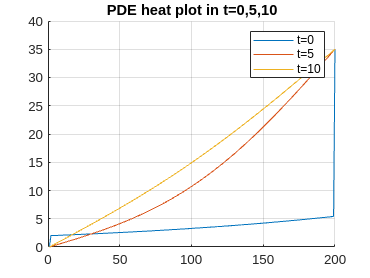

figure;
hold on;
plot(pde(1,:), 'DisplayName', 't=0');
plot(pde(101,:), 'DisplayName', 't=5');
plot(pde(201,:), 'DisplayName', 't=10');
title('PDE heat plot in t=0,5,10');
grid on;
legend show;
hold off;

همانطور که می بینید دما به مرور در طول میله پخش می شود و در آخر در میله از انتها که دما ۲۰۰ دارد تا ابتدای میله که دمای صفر دارد به صورت خطی کاهش پیدا می کند و این یعنی میله به تعادل رسیده اما در زمان ۵ هنوز کمی منحنی خمیده است و این یعنی هنوز به تعادل نرسیده.

### 2d plot for all t,x

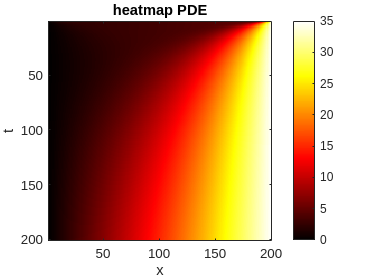

imagesc(pde)
colormap hot
colorbar
xlabel('x');
ylabel('t');
title('heatmap PDE');

همانطور که می بینید حرارت ابتدا در نقطه ۲۰۰ جمع است اما با گذشت زمان در میله پخش می شود و باقی میله هم افزاش حرارت را تجربه می کنند مثلا در اواخر دمای وسط میله چیزی حدود ۱۵ می شود که حرف ما را تایید می کند.

### split x to 100 and t to 101

new_x = linspace(0,1,100);
new_t = linspace(0,10,101);
pde2 = pdepe(m,@pde_heat,@ic_heat,@bc_heat,new_x,new_t);

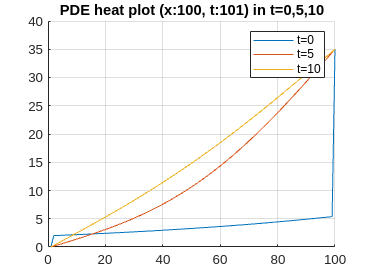

figure;
hold on;
plot(pde2(1,:), 'DisplayName', 't=0');
plot(pde2(51,:), 'DisplayName', 't=5');
plot(pde2(101,:), 'DisplayName', 't=10');
title('PDE heat plot (x:100, t:101) in t=0,5,10');
grid on;
legend show;
hold off;

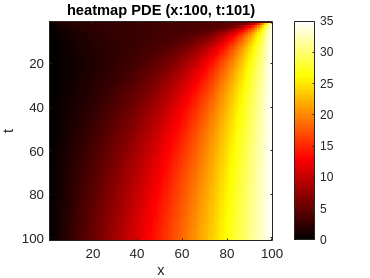

imagesc(pde2)
colormap hot
colorbar
xlabel('x');
ylabel('t');
title('heatmap PDE (x:100, t:101)');

### 3d plot

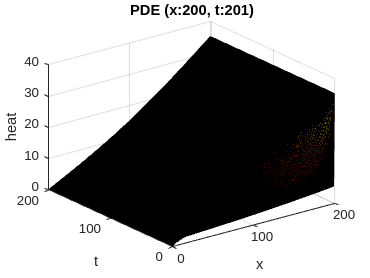

figure;
surf(pde);
colormap hot
xlabel('x');
ylabel('t');
zlabel('heat');
title('PDE (x:200, t:201)');

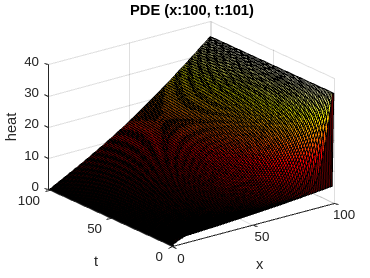

figure;
surf(pde2);
colormap hot
xlabel('x');
ylabel('t');
zlabel('heat');
title('PDE (x:100, t:101)');

## part 2


$$1. \text{معادله موج:} \\
\frac{\partial^2 u}{\partial t^2} = c^2 \nabla^2 u \\
\\
2. \text{جداسازی متغیرها:} \\
u(x, y, z, t) = X(x) Y(y) Z(z) T(t) \\
\\
\text{جایگذاری در معادله موج:} \\
X(x) Y(y) Z(z) \frac{d^2 T(t)}{dt^2} = c^2 T(t) \left( \frac{d^2 X(x)}{dx^2} + \frac{d^2 Y(y)}{dy^2} + \frac{d^2 Z(z)}{dz^2} \right) \\
\\
\text{تقسیم دو طرف بر } X(x) Y(y) Z(z) T(t): \\
\frac{1}{T(t)} \frac{d^2 T(t)}{dt^2} = c^2 \left( \frac{1}{X(x)} \frac{d^2 X(x)}{dx^2} + \frac{1}{Y(y)} \frac{d^2 Y(y)}{dy^2} + \frac{1}{Z(z)} \frac{d^2 Z(z)}{dz^2} \right) \\
\\
\text{هر طرف باید برابر با یک ثابت باشد:} \\
\frac{1}{T(t)} \frac{d^2 T(t)}{dt^2} = -k^2 \\
c^2 \left( \frac{1}{X(x)} \frac{d^2 X(x)}{dx^2} + \frac{1}{Y(y)} \frac{d^2 Y(y)}{dy^2} + \frac{1}{Z(z)} \frac{d^2 Z(z)}{dz^2} \right) = -k^2 \\
\\
3. \text{بخش زمانی:} \\
\frac{d^2 T(t)}{dt^2} + k^2 T(t) = 0 \\
\text{حل معادله:} \\
T(t) = A \cos(kt) + B \sin(kt) \\
\\
4. \text{بخش مکانی:} \\
\frac{d^2 X(x)}{dx^2} + \frac{d^2 Y(y)}{dy^2} + \frac{d^2 Z(z)}{dz^2} + \frac{k^2}{c^2} X(x) Y(y) Z(z) = 0 \\
\\
5. \text{معادله هلمهولتز:} \\
\text{برای فرکانس مشخص } \omega \text{، بگذارید } k = \frac{\omega}{c}. \text{ معادله هلمهولتز به صورت زیر است:} \\
\nabla^2 u + k^2 u = 0 \\$$


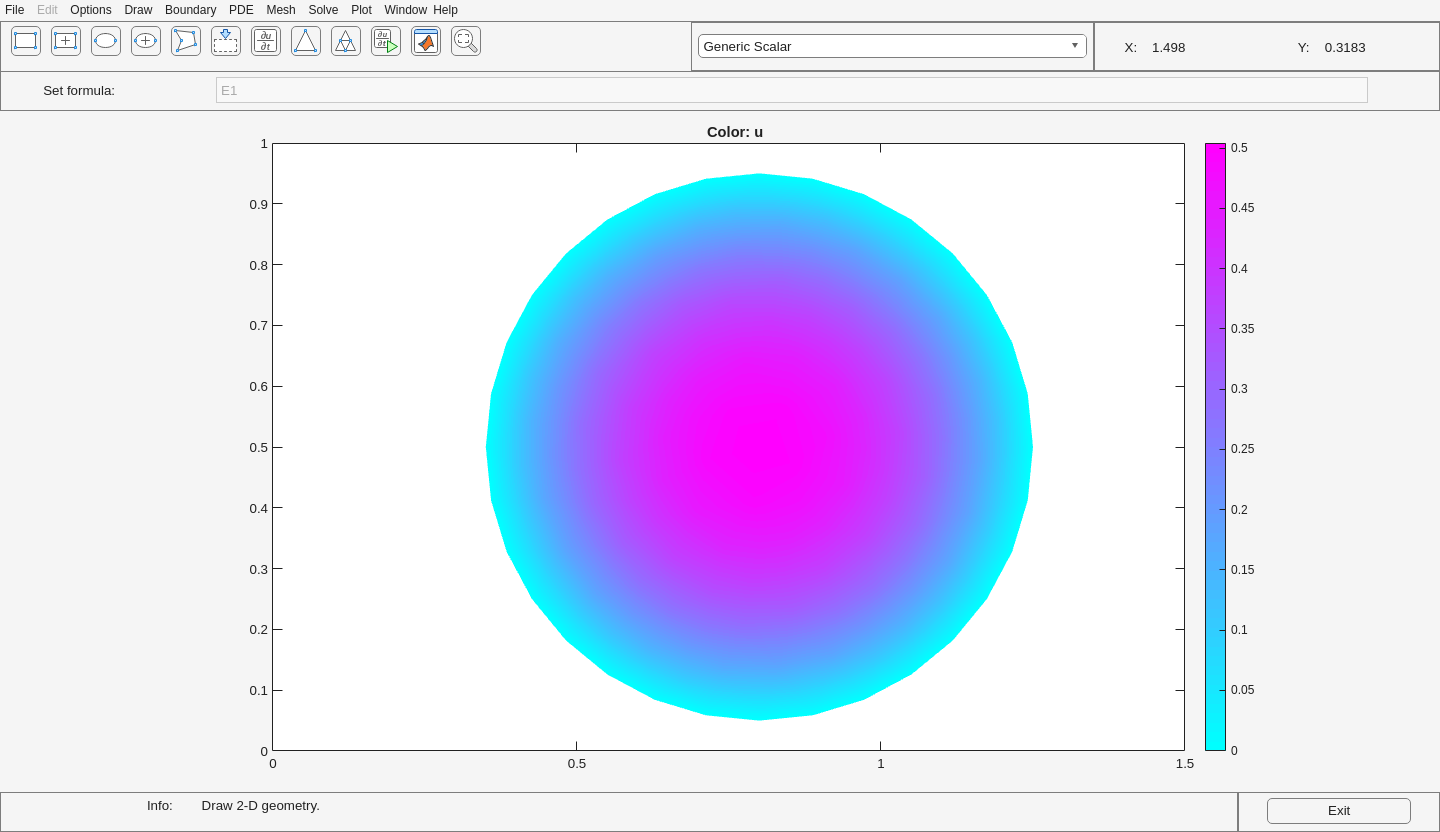

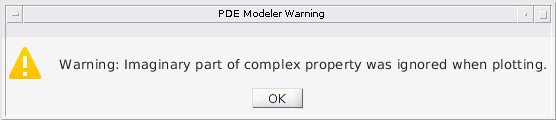

% function pdemodel
[pde_fig,ax]=pdeinit;
pdetool('appl_cb',1);
set(ax,'DataAspectRatio',[1 1 1]);
set(ax,'PlotBoxAspectRatio',[1.5 1 2]);
set(ax,'XLim',[0 1.5]);
set(ax,'YLim',[0 1]);
set(ax,'XTickMode','auto');
set(ax,'YTickMode','auto');

% Geometry description:
pdeellip(0.80000000000000004,0.5,0.45000000000000001,0.45000000000000001,...
0,'E1');
set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','E1')

% Boundary conditions:
pdetool('changemode',0)
pdesetbd(4,...
'neu',...
1,...
'-60i',...
'0')
pdesetbd(3,...
'neu',...
1,...
'-60i',...
'0')
pdesetbd(2,...
'neu',...
1,...
'-60i',...
'0')
pdesetbd(1,...
'neu',...
1,...
'-60i',...
'0')

% Mesh generation:
setappdata(pde_fig,'Hgrad',1.3);
setappdata(pde_fig,'refinemethod','regular');
setappdata(pde_fig,'jiggle',char('on','mean',''));
setappdata(pde_fig,'MesherVersion','preR2013a');
pdetool('initmesh')

% PDE coefficients:
pdeseteq(1,...
'1.0',...
'0.0',...
'10.0',...
'1.0',...
'0:10',...
'0.0',...
'0.0',...
'[0 100]')
setappdata(pde_fig,'currparam',...
['1.0 ';...
'0.0 ';...
'10.0';...
'1.0 '])

% Solve parameters:
setappdata(pde_fig,'solveparam',...
char('0','1000','10','pdeadworst',...
'0.5','longest','0','1E-4','','fixed','Inf'))

% Plotflags and user data strings:
setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 0 0 0 1 1 0 0 0 0 1]);
setappdata(pde_fig,'colstring','');
setappdata(pde_fig,'arrowstring','');
setappdata(pde_fig,'deformstring','');
setappdata(pde_fig,'heightstring','');

% Solve PDE:
pdetool('solve')

ابتدا لازم به ذکر است که بخش موهومی جواب در نمودار نمایش داده نشده.

همانطور که می بینید موج ما در این معادله از مرکز دایره شروع به انتشار می کند و دامنه در مرکز دایره بیشتر است و با نزدیک شدن به لبه ها اندازه دامنه کاهش پیدا می کند. این موضوع به صورت شعاعی و متقارن صورت می گیرد